**READ ME**

This code is only made for cases in problem 1 and problem 2 and solves using linear finite element basis functions.

*When asked for question Number :*

*    - Enter "1" :  for first problem where both the end forces are given.*

*    - Enter "2" : for second problem where both the ends are fixed.*

- k can be 0 or any other number.

- axial force distribution can be a number or a function of x.

Q = input('Enter the question number :' );

if Q == 1

    syms x

    EA = input('Enter the value of EA:  ');
    k = input('spring constant assosciated with the member, k = ');
    x_0 = 0 ;
    x_L = input('Enter the length of the bar:  ');
    nel  = input('Enter the number of elements:  ');

    K = zeros(nel+1,nel+1);
    F = zeros(nel+1,1);

    h = (x_L - x_0)/nel;

    x1 = 0:h:(x_L-h);
    x2 = h:h:x_L;

    while true
        f = input('Distribution (use small letter "x" if it is a variable) of axial force = ')

f = 10

Boundary condition at x = 0


        P_0 = input('Give the force at the end x = 0 :  ')

P_0 = 0

Boundary condition at x = L


        P_L = input('Give the force at the end x = L :  ')

P_L = 10


        if k == 0
            if int(f*(h-x)/h,0,L) + P_L - P_0 == 0
                break
            else
                fprintf('If spring constant assosciated with the member, k = 0, then,\n there must be a force equilibrium balance to have a solution.\n Kindly update the values of forces at both ends and the axial\n distribution of forces accordingly.')
                continue
            end
        else
            break
        end
    end


    for e = 1:nel

        FF = zeros(2,1);
        KK = zeros(2);

        X1 = x1(e);
        X2 = x2(e);

        N1 = (X2 - x)/h;
        N2 = (x - X1)/h;

        N = [N1,N2];
        dN = diff(N);

        for ii = 1:2
            FF(ii) = FF(ii) + Gauss_Legendre_Integration(f*N(ii),1,X1,X2);
            for j = 1:2
                KK(ii,j) = KK(ii,j) + Gauss_Legendre_Integration(EA*dN(ii)*dN(j) + k*N(1)*N(2),2,X1,X2);
            end
        end
        for ii = 1:2
            ig = e + (ii-1);
            F(ig) = F(ig) + FF(ii);
            for j = 1:2
                jg = e + (j-1);
                K(ig,jg) = K(ig,jg) + KK(ii,j);
            end
        end
    end
    F(1) = F(1) + P_0;
    F(end) = F(end) + P_L;

    if k == 0
        K(1,:) = 0;
        K(:,1) = 0;
        K(1,1) = 1;
        fprintf('Since k = 0, with boundary condition type-2 at both ends\n there are infinite possible solutions. Out of the infinite solutions possible, \n one solution where the displacement at x = 0 is displayed!')
    end

    Alpha = K\F;

    for ii = 1:nel

        X1 = x1(ii);
        X2 = x2(ii);

        N1 = (X2 - x)/h;
        N2 = (x - X1)/h;

        U(ii) = Alpha(ii)*N1 + Alpha(ii+1)*N2;
    end


Plotting 

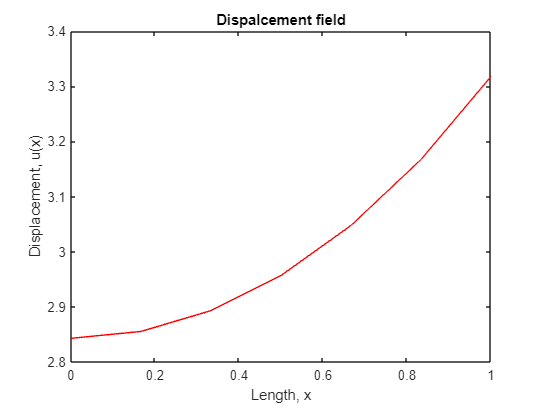

    figure();
    for ii = 1:nel
        t = linspace(x1(ii),x2(ii),20);
        u = double(subs(U(ii),x,t));
        plot(t,u,'r','Linewidth',0.2);
        hold on
    end
    title("Dispalcement field")
    xlabel("Length, x")
    ylabel("Displacement, u(x)")

else

    syms x

    EA = input('Enter the value of EA:  ');
    k = input('spring constant assosciated with the member, k = ');
    x_0 = 0 ;
    x_L = input('Enter the length of the bar:  ');
    nel  = input('Enter the number of elements:  ');

    K = zeros(nel+1,nel+1);
    F = zeros(nel+1,1);

    h = (x_L - x_0)/nel;

    x1 = 0:h:(x_L-h);
    x2 = h:h:x_L;


    f = input('Distribution (use small letter "x" if it is a variable) of axial force = ')

Boundary condition at x = 0


    U_0 = input('Give the displacement at the end x = 0 :  ')


Boundary condition at x = L


    U_L = input('Give the displacement at the end x = L :  ')



    for e = 1:nel

        FF = zeros(2,1);
        KK = zeros(2,2);

        X1 = x1(e);
        X2 = x2(e);

        N1 = (X2 - x)/h;
        N2 = (x - X1)/h;

        N = [N1,N2];
        dN = diff(N);

        for ii = 1:2
            FF(ii) = FF(ii) + Gauss_Legendre_Integration(f*N(ii),1,X1,X2);
            for j = 1:2
                KK(ii,j) = KK(ii,j) + Gauss_Legendre_Integration(EA*dN(ii)*dN(j) + k*N(1)*N(2),2,X1,X2);
            end
        end
        for ii = 1:2
            ig = e + (ii-1);
            F(ig) = F(ig) + FF(ii);
            for j = 1:2
                jg = e + (j-1);
                K(ig,jg) = K(ig,jg) + KK(ii,j);
            end
        end
    end
    K(1,:) = 0;
    F(1) = 0;
    K(:,1) = 0;

 
strain =
 
   [0.07495376, 0.22625578, 0.38176719, 0.54438126, 0.71712336, 0.90320727]


    K(1,1) = 1;

xvals =     0.1667    0.3333    0.5000    0.6667    0.8333    1.0000


g =      1     6


    K(:,end) = 0;

gg = 6

    K(end,:) = 0;

xx = xx(:,:,1,1,1,1) =

     0     0


xx(:,:,2,1,1,1) =

     0     0


xx(:,:,3,1,1,1) =

     0     0


xx(:,:,1,2,1,1) =

     0     0


xx(:,:,2,2,1,1) =

     0     0


xx(:,:,3,2,1,1) =

     0     0


xx(:,:,1,3,1,1) =

     0     0


xx(:,:,2,3,1,1) =

     0     0


xx(:,:,3,3,1,1) =

     0     0


xx(:,:,1,4,1,1) =

     0     0


xx(:,:,2,4,1,1) =

     0     0


xx(:,:,3,4,1,1) =

     0     0


xx(:,:,1,1,2,1) =

     0     0


xx(:,:,2,1,2,1) =

     0     0


xx(:,:,3,1,2,1) =

     0     0


xx(:,:,1,2,2,1) =

     0     0


xx(:,:,2,2,2,1) =

     0     0


xx(:,:,3,2,2,1) =

     0     0


xx(:,:,1,3,2,1) =

     0     0


xx(:,:,2,3,2,1) =

     0     0


xx(:,:,3,3,2,1) =

     0     0


xx(:,:,1,4,2,1) =

     0     0


xx(:,:,2,4,2,1) =

     0     0


xx(:,:,3,4,2,1) =

     0     0


xx(:,:,1,1,3,1) =

     0     0


xx(:,:,2,1,3,1) =

     0     0


xx(:,:,3,1,3,1) =

     0     0


xx(:,:,1,2,3,1) =

     0     0


xx(:,:,2,2,3,1) =

     0     0


xx(:,:,3,

    F(end) = 0;

yy = yy(:,:,1,1,1,1) =

     0     0


yy(:,:,2,1,1,1) =

     0     0


yy(:,:,3,1,1,1) =

     0     0


yy(:,:,1,2,1,1) =

     0     0


yy(:,:,2,2,1,1) =

     0     0


yy(:,:,3,2,1,1) =

     0     0


yy(:,:,1,3,1,1) =

     0     0


yy(:,:,2,3,1,1) =

     0     0


yy(:,:,3,3,1,1) =

     0     0


yy(:,:,1,4,1,1) =

     0     0


yy(:,:,2,4,1,1) =

     0     0


yy(:,:,3,4,1,1) =

     0     0


yy(:,:,1,1,2,1) =

     0     0


yy(:,:,2,1,2,1) =

     0     0


yy(:,:,3,1,2,1) =

     0     0


yy(:,:,1,2,2,1) =

     0     0


yy(:,:,2,2,2,1) =

     0     0


yy(:,:,3,2,2,1) =

     0     0


yy(:,:,1,3,2,1) =

     0     0


yy(:,:,2,3,2,1) =

     0     0


yy(:,:,3,3,2,1) =

     0     0


yy(:,:,1,4,2,1) =

     0     0


yy(:,:,2,4,2,1) =

     0     0


yy(:,:,3,4,2,1) =

     0     0


yy(:,:,1,1,3,1) =

     0     0


yy(:,:,2,1,3,1) =

     0     0


yy(:,:,3,1,3,1) =

     0     0


yy(:,:,1,2,3,1) =

     0     0


yy(:,:,2,2,3,1) =

     0     0


yy(:,:,3,

    K(end,end) = 1;
    Alpha = K\F;

    for ii = 1:nel

        X1 = x1(ii);
        X2 = x2(ii);

        N1 = (X2 - x)/h;
        N2 = (x - X1)/h;


Unable to perform assignment because the left and right sides have a different number of elements.

        U(ii) = Alpha(ii)*N1 + Alpha(ii+1)*N2;
    end


Plotting 

    figure();
    for ii = 1:nel
        t = linspace(x1(ii),x2(ii),20);
        u = double(subs(U(ii),x,t));
        plot(t,u,'r','Linewidth',0.2);
        hold on
    end
    title("Dispalcement field")
    xlabel("Length, x")
    ylabel("Displacement, u(x)")
end


**Post Processing**

strain = diff(U)
xvals = h:h:x_L
g = size(xvals)
gg = double(g(2))
xx = zeros(1:gg)
yy = zeros(1:gg)
for ii = 1:gg
    if ii==1
        polyfit
    elseif ii==gg
        xx(ii) = [xvals(gg:gg-1)]
        yy(ii) = [strain(gg:gg-1)]
    else
        xx(ii) = [xvals(ii-1:ii+1)]
        yy(ii) = [strain(ii-1:ii+1)]
    end
end

